x = 0:0.1:(6*pi)

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


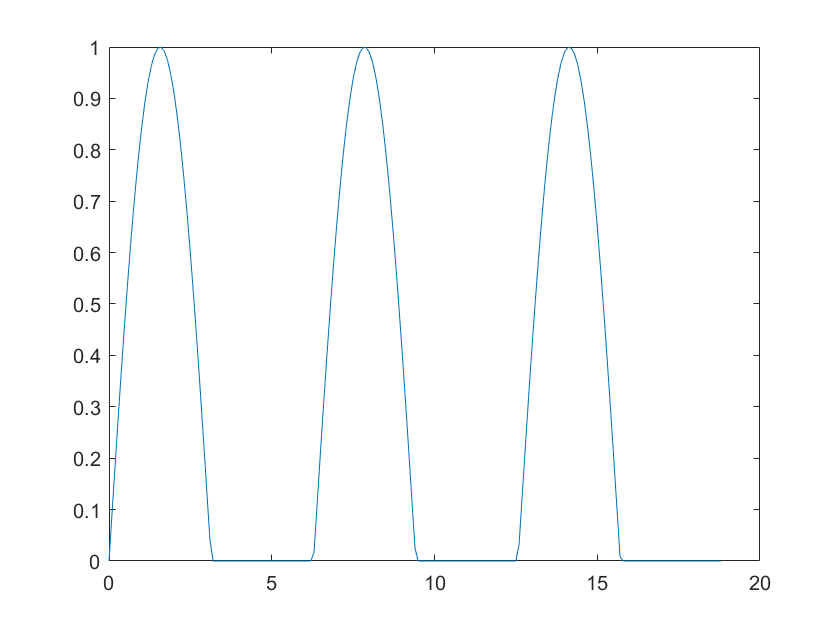

y=sin(x);% Generate Sine Wave  
y(y<0) = 0;                       % Rectified Sine Wave
plot(x,y);


F = [x
     y]

F =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000
         0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


L1 = 2; 
L2 = 3; 
theta1 = pi; 
theta2 = pi; 

J = jacobian(L1, L2, theta1, theta2)

J =     0.0000    0.0000
    1.0000    3.0000



torque = J\F

torque = 	1.0e+16 *

         0    0.0408    0.0817    0.1225    0.1633    0.2041    0.2450    0.2858    0.3266    0.3675    0.4083    0.4491    0.4899    0.5308    0.5716    0.6124    0.6532    0.6941    0.7349    0.7757    0.8166    0.8574    0.8982    0.9390    0.9799    1.0207    1.0615    1.1024    1.1432    1.1840    1.2248    1.2657    1.3065    1.3473    1.3882    1.4290    1.4698    1.5106    1.5515    1.5923    1.6331    1.6740    1.7148    1.7556    1.7964    1.8373    1.8781    1.9189    1.9597    2.0006
         0   -0.0136   -0.0272   -0.0408   -0.0544   -0.0680   -0.0817   -0.0953   -0.1089   -0.1225   -0.1361   -0.1497   -0.1633   -0.1769   -0.1905   -0.2041   -0.2177   -0.2314   -0.2450   -0.2586   -0.2722   -0.2858   -0.2994   -0.3130   -0.3266   -0.3402   -0.3538   -0.3675   -0.3811   -0.3947   -0.4083   -0.4219   -0.4355   -0.4491   -0.4627   -0.4763   -0.4899   -0.5035   -0.5172   -0.5308   -0.5444   -0.5580   -0.5716   -0.5852   -0.5988   -0.6124   -0.6260   -0.63

function J = jacobian(L1, L2, theta1, theta2)
    J = [(-L1 * sin(theta1) - L2 * sin(theta1+theta2)) (-L2 * sin(theta1+theta2))
         (L1 * cos(theta1) + L2 * cos(theta1+theta2))  (L2 * cos(theta1+theta2))];
end